## **Cystinosis Disease Detector**

### **Cargar datos:**

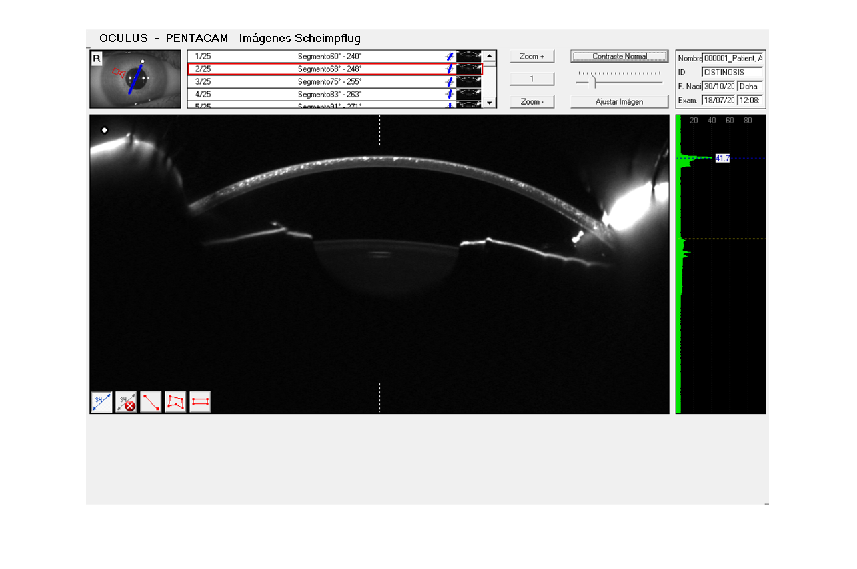

I = imread( '../data/OD1con_Cistinosis/CISTINOSIS_20160718_120806_PENTACAM_R_02.BMP' );
figure,
imshow( I );

### Preprocesamiento 

Cortar la imagen a unas dimensiones que eliminen ruido y la interfaz de usuario.

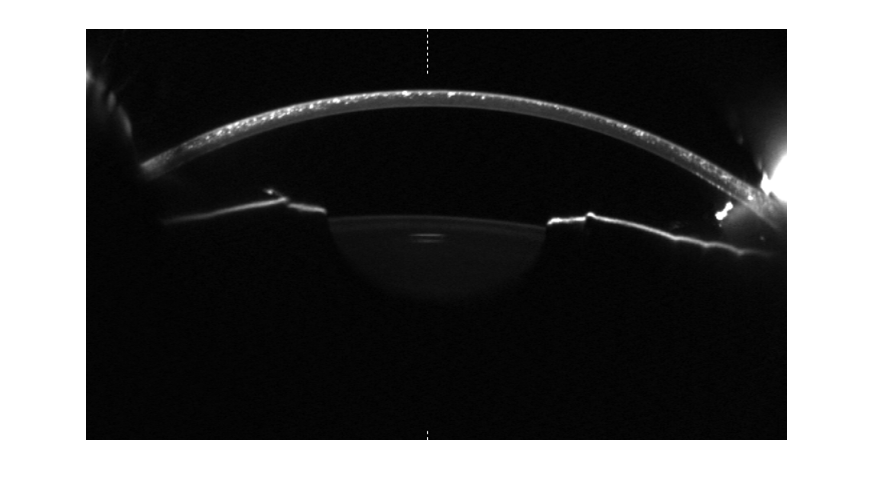

I = imcrop( I,[100, 130, 700, 410] );
I = rgb2gray(I);
figure,
imshow(I);

Obtener el centro del ojo siguiendo la marca de la pupila.

% Get the center of the eye
croped = imcrop( I,[0, size(I,1)-10, size(I,2), 10] );
bin = imbinarize( croped, 0.35 );
[row, center] = find(bin, 1, 'last');

Ecualizar la imagen y aplicar una erosion para quitar lad formas innecesarias, depues binarizar utilizando una binarización adaptativa con una sensitividad de 0.000001.

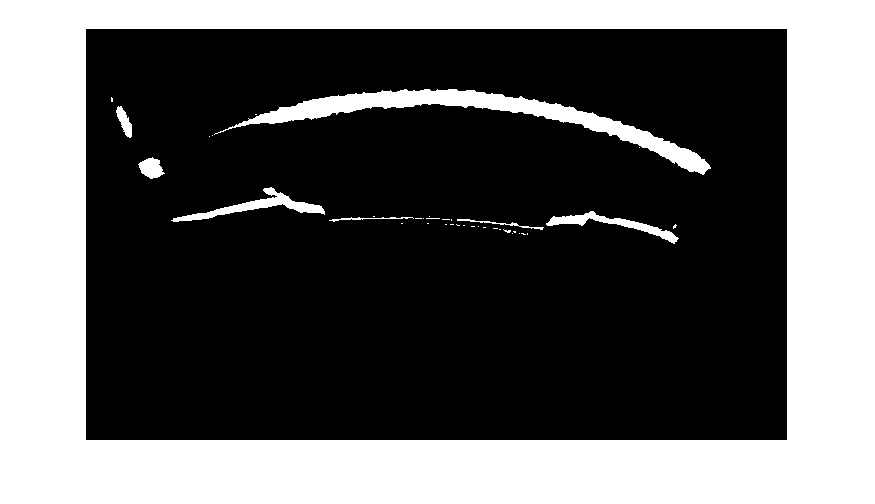

% Equilize the image
J = histeq(I);
% Create erode objects
se = strel('disk',5);
% Erode image
S = imerode(J, se);

% binarize the image
bin = imbinarize(S, "adaptive", "sensitivity", 0.000001);

%less = bwareaopen(bin,700);

% Mask the image with the original one 
tmp = bsxfun(@times, I, uint8(bin));
% binarize the imge to extract features
bin_t = imbinarize(tmp, 0.1);
figure,
imshow(bin_t);

Segmentar la imagen aplicando una filtro de características en base de un rectangulo global que no sigue la orientación del objeto (BoundingBox) para obtener objetos de interés. Una vez detectados los diferentes rectangulos se filtran y se selecciona el rectanculo más ancho de todos que este será el que contendrá la córnea. 

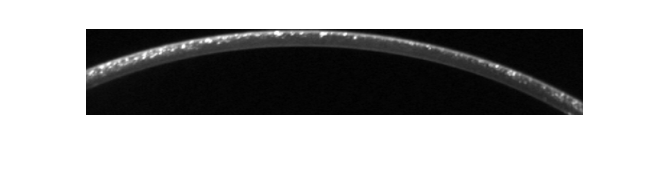

%Segment the image extracting a boxe for each object
s = regionprops(bin_t, "BoundingBox");

% Get the box with the maximum width
maxm = s(1);
for i=1 : size(s)-1
    en = s(i+1);
    if en.BoundingBox(3)> maxm.BoundingBox(3)
        maxm = en;
    end
end

bb = floor(maxm.BoundingBox);

% Obtain relative position in the cropped cornea
diff = center - bb(1);

% Crop the cornea
cornea = I( bb(2)+1:bb(2)+bb(4), bb(1)+1:bb(1)+bb(3) );
figure,
imshow(cornea);

### Procesamiento:

Aplanar la córnea detectada.

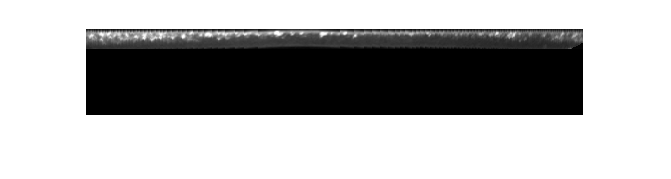

%flatting the cornea
threshold = 0.15;
cornea_bin = imbinarize(cornea, threshold);
[rows, cols] = size( cornea );
for j = 1:cols
    i = 1;
    new_i = 1;
    if cornea_bin(i,j) < 1
        while cornea_bin(i,j) < 1 && i < rows
            i=i+1;
        end
        cornea_limit = i + 20;
        i=i-1;
        while i < cornea_limit && i < rows
            aux = cornea(i,j);
            cornea(i,j) = 0;
            cornea(new_i,j) = aux;
            new_i = new_i+1;
            i = i+1;
        end
    end
end
%removing the rest
for j = 1:cols
    for i = 21:rows
        cornea(i,j) = 0;
    end
end

figure,
imshow(cornea);

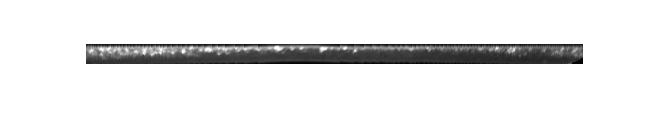


threshold = 0.05;
I_pin_b = imbinarize( cornea, threshold );
s = regionprops( I_pin_b, 'BoundingBox');
maxm = s(1);
for i=1 : size(s)-1
    en = s(i+1);
    if en.BoundingBox(3)> maxm.BoundingBox(3)
        maxm = en;
    end
end
bb = floor(maxm.BoundingBox);
cornea = cornea( bb(2)+1:bb(2)+bb(4), bb(1)+1:bb(1)+bb(3) );
figure,
imshow(cornea)

Cortar la cornea aplanada en 6 secciones, partiendo de que el trozo medio en horizontal tendrá 1/3 de las columnas y el primer trozo en vertical tendrá 2/3 de las filas.

nrows = size(cornea, 1);
ncols = size(cornea, 2);
c_stp = floor(ncols*(1/3));
mid = floor(c_stp/2);
r_stp = floor(nrows*(2/3));
sections = cell( 6, 1);
sections{1} = imcrop( cornea, [0, 0, diff-mid, r_stp] );
sections{2} = imcrop( cornea,[(diff-mid)+1, 0, c_stp, r_stp] );
sections{3} = imcrop( cornea, [(diff+mid)+1, 0, ncols-(diff+mid), r_stp] );
sections{4} = imcrop( cornea, [0, r_stp, diff-mid, nrows-r_stp] );
sections{5} = imcrop( cornea,[(diff-mid)+1, r_stp, c_stp, nrows-r_stp] );
sections{6} = imcrop( cornea, [(diff+mid)+1, r_stp, ncols-(diff+mid), nrows-r_stp] );

### Postprocesamiento

Extrater resultados. El numero de grises y el numero de cristales en cada sección de la córnea.

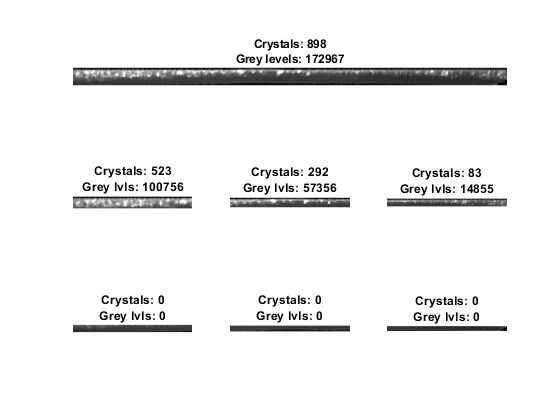

crystals = imbinarize( cornea, 0.625 );
crystals_sections = cell( 6, 1);
grey_sections = cell( 6, 1);

figure,
subplot(3,3,[1,2,3]);
imshow(cornea);
% getting the crystals in the cornea
[ counts, binLocations ] = imhist( crystals );
%counting the grey level in the crystals
grey = bsxfun( @times, cornea, uint8(crystals) );
[ counts2, binLocations2 ] = imhist( grey );
grey_lvl = 0;
for j = 1:size( counts2 )
    grey_lvl = grey_lvl + counts2(j)*binLocations2(j);
end
tit = sprintf("Crystals: %i\nGrey levels: %i", counts(2), grey_lvl );
title( tit );

for i=1:6
    subplot(3,3,3+i);
    imshow( sections{i} );
    %counting the crystals
    bin = imbinarize( sections{i}, 0.625 );
    [ counts, binLocations ] = imhist( bin );
    crystals_sections{i} = counts(2);
    %counting the grey level in the crystals
    grey = bsxfun( @times, sections{i}, uint8(bin) );
    [ counts, binLocations ] = imhist( grey );
    tmp = 0;
    for j = 1:size( counts )
        tmp = tmp + counts(j)*binLocations(j);
    end
    grey_sections{i} = tmp;
    tit = sprintf("Crystals: %i\nGrey lvls: %i", crystals_sections{i}, grey_sections{i} );
    title( tit );
end